# Demonstration of a PnP operation for a DGU Network

clear
close all
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

- Initialize Network: Complete configuration of the network with all the electrical parameters is load from a text file

utils = utilityFunctions;
PnP = operationPnP;
config = "DISTRIBUTED"; % distributed config, for plot function
filename = 'config_DGU_1.txt';
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0



dguNet = DGU_network(nb_subsystems); % Instantiate a DGU NETWORK class

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.975, 50.1, nb_subsystems);% references
Il = linspace(3.5, 5.5, nb_subsystems);
% set Electrical parameters and Dynamics for ALL the subsystems in the network
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end

### A) For now consider only 5 active DGU out of 6

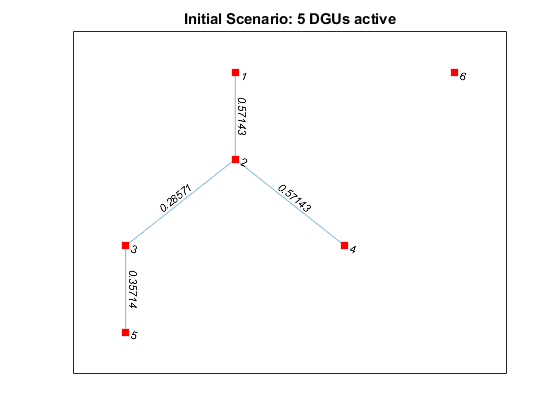

activeDGU_scen1 = 1:1:5; % Initially, 5 DGUs are active
Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8; 
Rij_mat = Rij_mat + tril(Rij_mat',1); % Non directed graph, symmetric matrix
dguNet = dguNet.setConnectionsGraph(Rij_mat); % set links between DGU
dguNet = dguNet.setActiveDGU(activeDGU_scen1); % define which DGUs are active
figure()
plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("Initial Scenario: 5 DGUs active");

dguNet = dguNet.initDynamics(); % initialize dynamics

For passivity based MPC, constraints are not in $\Delta$ Formulation 

delta_config = false; % not in delta configuration
dguNet = dguNet.compute_Ref_Constraints(delta_config);
control_type = "MPC online";
[x0, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config)

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Q_Ni = 1×6 cell array
    {4×4 double}    {8×8 double}    {6×6 double}    {4×4 double}    {4×4 double}    {2×2 double}


Ri = 1×6 cell array
    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}


- Use passivity to find the local passive feedback gains $K_i$ and $P_i$ s.t. $V_i(x_i) = x_i^T P_i x_i$

dguNet = PnP.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0103   -0.1017



ans = "P2"

    2.9528    0.5446
    0.5446    4.1612



ans = "K3"

   -0.4957   -0.1504



ans = "P3"

   24.7525    2.1795
    2.1795    1.0425



ans = "K4"

   -0.1136   -0.1017



ans = "P4"

   11.4766    1.4834
    1.4834    1.8648



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6917
    4.6917    1.6810



- Use the tracking MPC with reconfigurable terminal ingredients  to converge to reference from the initial state

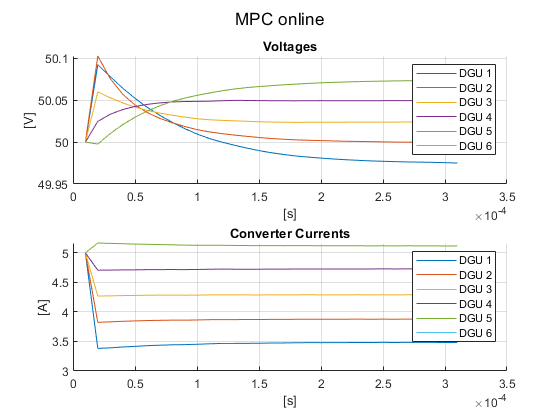

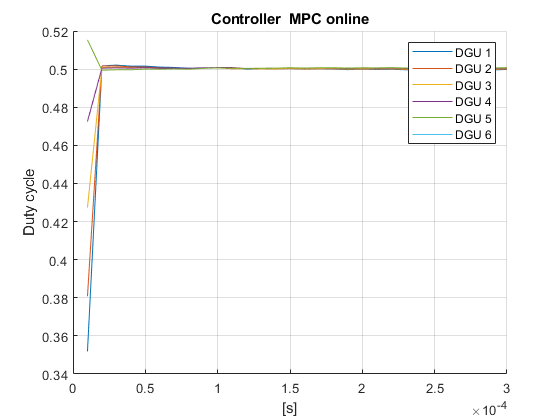

simStart = 1;
length_sim = 30;
[X, U] = PnP.mpc_DGU_tracking(@mpc_online_2, x0, length_sim, dguNet, Q_Ni, Ri);
dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart, 1:6); % plot results

### B) Scenario 2: Connect DGU 6 to DGU 3

Set all DGUs to be active. DGU 6 is now active but is not connected yet to the network

simStart2 = simStart + length_sim + 1;
dguPos = 6;
activeDGU_scen2 = 1:1:6; % Now all the 6 DGUs are active
dguNet = dguNet.setActiveDGU(activeDGU_scen2);
dguNet2 = dguNet; % dguNet copy, with 6 active DGU but before connection

Create connection from DGU 6 to DGU 3. For this purpose, a new instance of the network class is created with the modified structure e.g. different Laplacian matrix and $A_{Ni}$ 

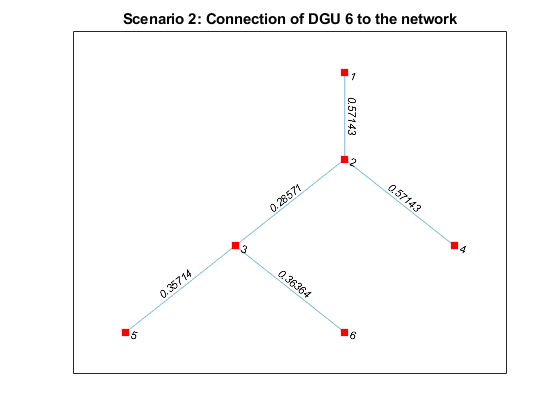

Rij_mat(3,dguPos) = 2.75; Rij_mat(dguPos,3) = Rij_mat(3,dguPos);  % New link
dguNet2 = dguNet2.setConnectionsGraph(Rij_mat);
dguNet2 = dguNet2.initDynamics(); % recompute Dynamics (changed with integration of DGU 6)
plot(dguNet2.NetGraph, 'EdgeLabel', dguNet2.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario 2: Connection of DGU 6 to the network')

dguNet2 = dguNet2.compute_Ref_Constraints(delta_config);

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 6 (including DGU 6 itself)

dguNet2 = PnP.redesignPhase(dguNet2, dguNet2.NetGraph,dguPos, "add");

ans = "New passive controller gain of system 3"

   -0.4650   -0.1511

    0.5256



ans = "New passive controller gain of system 6"

   -0.5574   -0.1421

    1.2941



Re-define Q_Ni since neighbors of DGU 3 and 6 changed. Initial values for the 5 first DGUs taken from previous simulation end. 

[x0, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2, delta_config); 
for i = activeDGU_scen1
    x0{i} = X{end}(:,i);   %
end
disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   49.9750
   -0.0167

 
 
x0{2} =
 
   49.9993
   -0.0228

 
 
x0{3} =
 
   50.0238
   -0.0115

 
 
x0{4} =
 
   50.0491
    0.0273

 
 
x0{5} =
 
   50.0735
    0.0175

 
 
x0{6} =
 
   50.0000
   -0.5000

 


- **Transition Phase**: Compute steady-state value to reach to allow the plug-in of DGU 6 (*PnP permitted). *Drive the system (the 5 initial DGU's + the 6th DGU before connection) to this steady state.

[X2_trans,U2_trans,lenSim, xs,us,alpha]= PnP.transitionPhase(x0, dguNet, dguNet2, Qi, Ri, 'reference')

X2_trans = 1×39 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U2_trans = 1×38 cell array
    {[0.5000 0.5002 0.5004 0.5007 0.5009 0.5567]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.4990]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.4988]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.4990]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.4993]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.4995]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.4997]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.4999]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5000]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5001]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5002]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5003]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5004]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5005]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5006]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5006]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5007]}    {[0.4998 0.5000 0.5002 0.5005 0.5007 0.5007]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0.5007]}    {[0.4997 0.5000 0.5002 0.5005 0.5007 0

lenSim = 39

xs =    49.9750   50.0000   50.0250   50.0500   50.0750   50.1000
   -0.0143   -0.0214   -0.0107    0.0286    0.0179         0


us =     0.4997    0.5000    0.5002    0.5005    0.5008    0.5010


alpha =    -1.0164
   -0.4414
   -0.6352
   -2.2976
   -0.9793
   -0.9584


steady state for each of the DGU before plug in


Plug in of DGU 6. Set new references from this point.

dguNet2.Vr = linspace(49.95, 50.2, nb_subsystems);% references
dguNet2.Il = linspace(2.5, 7.5, nb_subsystems);
dguNet2 = dguNet2.compute_Ref_Constraints(delta_config);

Initial states for reference MPC tracking are the states from the end of the transition phase (i.e. corresponding to steady state where P&P permitted):

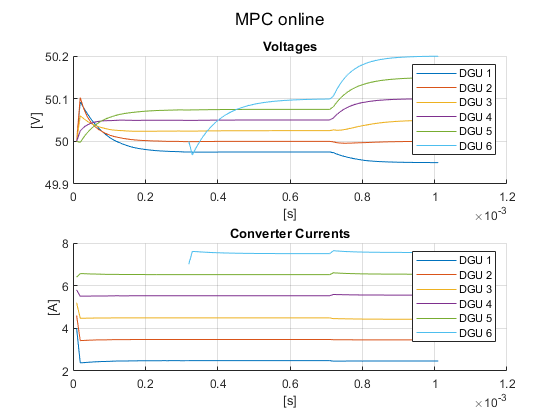

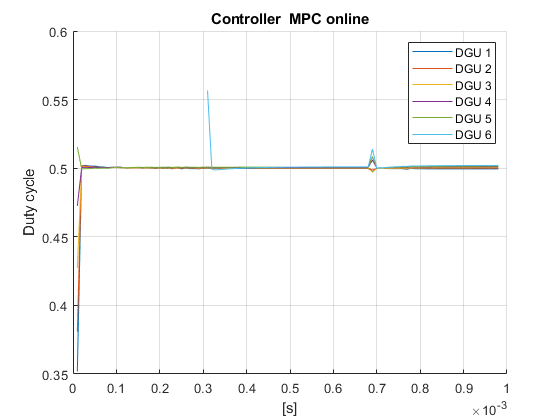

for i = activeDGU_scen2
    x0{i} = X2_trans{end}(:,i);   
end
lenSim2 = 30;
[X2, U2] = PnP.mpc_DGU_tracking(@mpc_online_2, x0, lenSim2, dguNet2, Q_Ni, Ri);
dguNet2.plot_DGU_system([X,X2_trans,X2],[U, U2_trans, U2], config, control_type, dguNet2, simStart, activeDGU_scen2); % plot results

#### C) 3rd Scenario: Plug out DGU 4

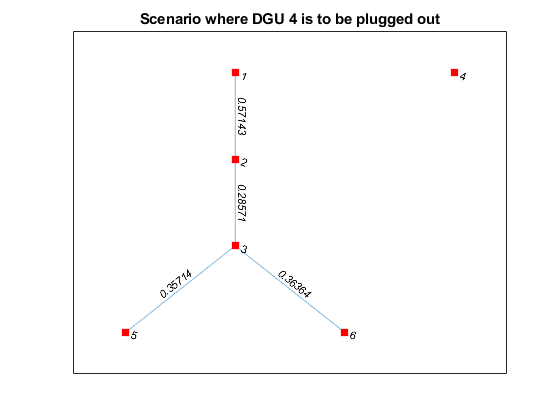

activeDGU_scen3 = [1 2 3 5 6]; % remove DGU 4 from active DGU list
dguNet3 = dguNet2; % copy the previous instance with 6 DGUs and create new instance for this scenario
dguNet3 = dguNet3.setActiveDGU(activeDGU_scen3);
dguDelete = 4;
Rij_mat(dguDelete,:) = 0; Rij_mat(:,dguDelete) = 0;
dguNet3 = dguNet3.setConnectionsGraph(Rij_mat);
dguNet3 = dguNet3.initDynamics();
plot(dguNet3.NetGraph, 'EdgeLabel', dguNet3.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario where DGU 4 is to be plugged out')

dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 4

dguNet3 = PnP.redesignPhase(dguNet3, dguNet2.NetGraph, dguDelete, "delete");

ans = "New passive controller gain of system 2"

   -0.0361   -0.1044

    0.2209



- **Transition Phase**: Take as initial state the end of simulation of scenario 2

% call again since dimension of Q_Ni change when adding/removing DGU
[~, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet3, delta_config);
for i = activeDGU_scen2
    x0{i} = X2{end}(:,i);   
end
disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   49.9501
   -0.0286

 
 
x0{2} =
 
   49.9999
   -0.0427

 
 
x0{3} =
 
   50.0495
   -0.0756

 
 
x0{4} =
 
   50.0998
    0.0573

 
 
x0{5} =
 
   50.1494
    0.0363

 
 
x0{6} =
 
   50.1995
    0.0551

 


Define new references, to see the effect of the objective function of the optimization problem:

dguNet3.Vr = linspace(49.90, 50.4, nb_subsystems);% references
dguNet3.Il = linspace(2.5, 7.5, nb_subsystems);
dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_0^i ||}^2$ will keep the steady state as close as possible to the current state: for quick P&P operation

[X3_trans_,U3_trans_,lenTrans_, xs_,us_,alpha_]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'current state')

Feasible steady-state found


X3_trans_ = 1×1 cell array
    {2×6 double}


U3_trans_ = 1×1 cell array
    {[0.4995 0.5000 0.5005 0.5010 0.5015 0.5020]}


lenTrans_ = 1

xs_ =    49.9500   49.9999   50.0495   50.0998   50.1494   50.1995
   -0.0285   -0.0428   -0.0760    0.0571    0.0357    0.0545


us_ =     0.4995    0.5000    0.5005    0.5010    0.5015    0.5020


alpha_ =    -1.1843
   -0.7038
   -0.6719
       NaN
   -1.0631
   -1.0358


$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_r^i ||}^2$ will keep the steady state as close as possible from the references, with the goal of reducing modification to the desired system behaviour

[X3_trans,U3_trans,lenTrans, xs,us,alpha]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'reference')

Feasible steady-state found


X3_trans = 1×41 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U3_trans = 1×40 cell array
    {[0.4938 0.5052 0.4993 0.5026 0.5139 0.5194]}    {[0.4996 0.4998 0.4998 0.5008 0.5007 0.5007]}    {[0.4996 0.4999 0.4998 0.5008 0.5009 0.5010]}    {[0.4995 0.5000 0.4999 0.5009 0.5011 0.5015]}    {[0.4994 0.5001 0.5000 0.5010 0.5014 0.5018]}    {[0.4994 0.5001 0.5000 0.5010 0.5016 0.5021]}    {[0.4993 0.5002 0.5001 0.5010 0.5017 0.5024]}    {[0.4993 0.5002 0.5002 0.5011 0.5019 0.5026]}    {[0.4992 0.5002 0.5003 0.5011 0.5020 0.5028]}    {[0.4992 0.5002 0.5004 0.5011 0.5022 0.5030]}    {[0.4992 0.5002 0.5005 0.5012 0.5023 0.5031]}    {[0.4991 0.5002 0.5005 0.5012 0.5023 0.5033]}    {[0.4991 0.5002 0.5006 0.5012 0.5024 0.5034]}    {[0.4991 0.5002 0.5006 0.5012 0.5025 0.5034]}    {[0.4991 0.5002 0.5007 0.5012 0.5026 0.5035]}    {[0.4991 0.5002 0.5007 0.5012 0.5026 0.5036]}    {[0.4991 0.5002 0.5008 0.5012 0.5027 0.5036]}    {[0.4991 0.5002 0.5008 0.5012 0.5027 0.5037]}    {[0.4991 0.5002 0.5008 0.5012 0.5027 0.5037]}    {[0.4991 0.5003 0.5008 0.5012 0.5028 0

lenTrans = 41

xs =    49.9017   50.0270   50.1004   50.1258   50.3000   50.4000
   -0.0716   -0.0058   -0.1592    0.0565    0.0713    0.1089


us =     0.4990    0.5003    0.5010    0.5013    0.5030    0.5040


alpha =    -1.1826
   -0.7034
   -0.6711
       NaN
   -1.0640
   -1.0367


If P&P permitted, simulate normal operation of the network after plug out of DGU 4:

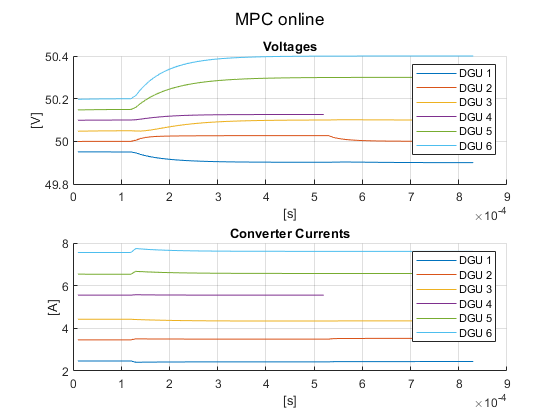

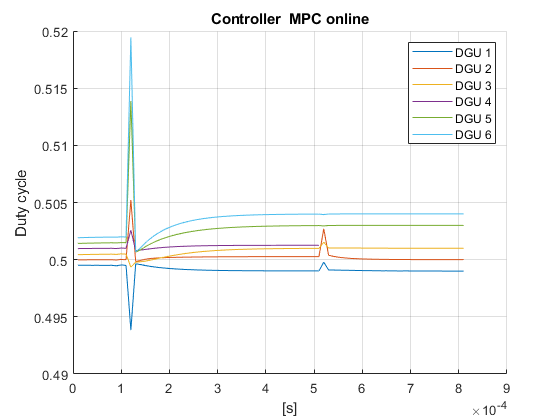

for i = activeDGU_scen3
    x0{i} = X3_trans{end}(:,i);   
end
lenSim3 = 30;
[X3, U3] = PnP.mpc_DGU_tracking(@mpc_online_2, x0, lenSim3, dguNet3, Q_Ni, Ri);
dguNet3.plot_DGU_system([X2(end-10:end), X3_trans, X3],[U2(end-10:end), U3_trans, U3], config, ...
                control_type, dguNet3, simStart, activeDGU_scen2); % plot results